# **3D visualisation of APT data**

The starting situation is a loaded pos file, loaded colorScheme, and a ranged mass spectrum (spec), see live script ***FirstSteps***.

Open a saved ranged mass spectrum if it is not loaded yet. Then select the the mass spectrum plot and enter and execute *spec = gco; *in the command line.

load colorScheme.mat
pos = posToTable;

file R56_01769-v01.pos loaded


## Extracting ions of the ranged mass spectrum

Then ranges must be extracted and the pos file needs to be parsed so that a column with *'ion'* is generated.

rng = rangesExtractFromMassSpec(spec);
options = 'decompose'

options = 'decompose'

pos = posAllocateRange(pos, rng, options);
 

## Plotting 3D-Data

For the subsquent 3D visualisation, the function *scatterPlotPosData* is needed.

*[p, ax] = scatterPlotPosData(pos,species,sample,colorScheme,size,plotAxis);*

### *Plotting of one species*

species = 'C' % which ion/atom species should be plotted; only one species: {'H'}

species = 'C'

sample = 1 % allows the specification of a subset to plot. If sample <1, it is a fraction of the overall number of atoms, if >1, it is a fixed number.

sample = 1

size = 1% size of the single atoms in the plot

size = 1

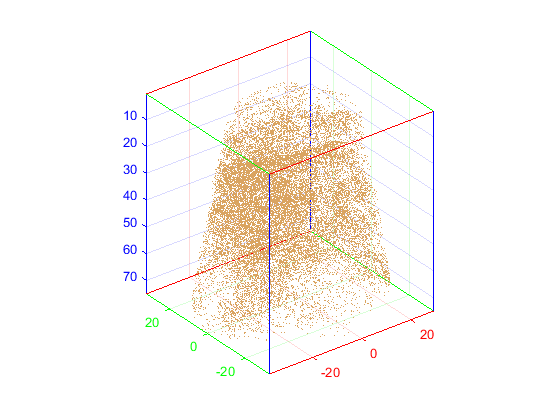

[p, ax] = scatterPlotPosData(pos,species,sample,colorScheme,size);

### Plotting of more species in more plots

species = {'C','Mn'} % which ion/atom species should be plotted in several plots; several species: {'A','B','C'}

species = 1×2 cell array
    {'C'}    {'Mn'}


sample = 1 % allows the specification of a subset to plot. If sample <1, it is a fraction of the overall number of atoms, if >1, it is a fixed number.

sample = 1

size = 1% size of the single atoms in the plot

size = 1

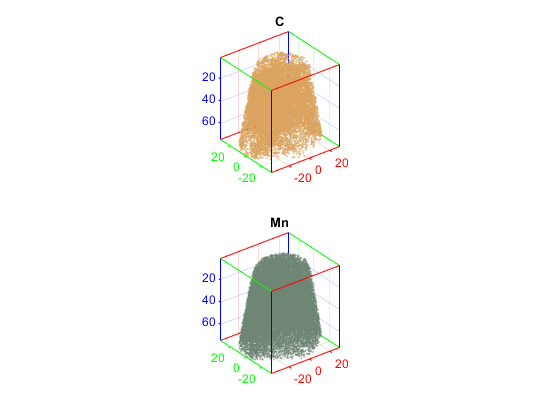

[p, ax] = scatterPlotPosData(pos,species,sample,colorScheme,size);

### Plotting of more species in one plot

For plotting atoms in **one plot **(with plotAxis input): *[p, ax] = scatterPlotPosData(pos, species, sample, colorScheme, size, ****axes(figure())****);*

species = {'C','Mn'} % which ion/atom species should be plotted in one plot; several species: {'A','B','C'}

species = 1×2 cell array
    {'C'}    {'Mn'}


sample = 1 % allows the specification of a subset to plot. If sample <1, it is a fraction of the overall number of atoms, if >1, it is a fixed number.

sample = 1

size = 1% size of the single atoms in the plot

size = 1

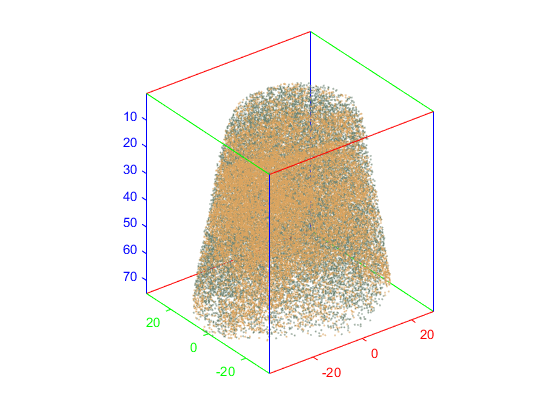

[p, ax] = scatterPlotPosData(pos,species,sample,colorScheme,size,axes(figure()));